# Run Analysis on Test Brain Data

This notebook walks through a simplified version of the entire thesis. We use a known volume downloaded from [https://projects.iq.harvard.edu/sparcdmri/Challenge_Data](https://projects.iq.harvard.edu/sparcdmri/Challenge_Data) to run the analysis - in the process of which we demonstrate how the analysis works. 

clear
close

### Setting up the experiment

In this section, we create an experiment object, in which we setup some parameters of the phantom data. One of the contributions of this paper is a table of $\lambda$ values that is parameterized on the number of fibers, the b-values, SNR and the order of the spherical harmonics model that's used. The $\lambda$ is computed per b-value (shell) and all of these parameters are stored in the `csaodfExperiment` object. 

expt = csaodfExperiment;

gt = gradientTable;
gt.readFromBvecBval("data/bvec.txt", "data/bvalue.txt");

expt.fibers = 1;                 % Estimated - this can't be known beforehand, but 2 is a good default (60% of voxels have crossings).
expt.SNR    = 30;                % This is also estimated from acquisition data.
expt.order  = 4;                 % Higher values here -> sharper reconstruction; also noisier.
expt.bvals  = gt.bValues;        % Ignore B0.

for x = 1:numel(expt.bvals)
    expt.lambda(x) = getLambda(expt.fibers, expt.bvals(x), expt.SNR, expt.order);
end

% Experimentally computed weights for Laplace Beltrami regularization
expt.lambda

ans =     0.0017    0.0006    0.0001


### Read data from volume

Reading data from a volume is easy - use the readFromNii function to populate v.

v = volume;
v.readFromNii("data/Gradient_60.nii");

### Compute Spherical Harmonics transformation matrix

Using the gradient directions from the table above, we can then compute the spherical harmonics transformation matrix can be computed. The inputs necessary are the table and the order of the harmonics.

SH = sphericalHarmonicsMatrix;
SH.make(gt.table, expt.order, 0);

### Process the volume!

processLive = false;

if processLive 
    ODFdata = expt.processVolume(v, gt, SH);
else
    % This is order 4
    d = load("data/ODFdataO4.mat");
    ODFdata = d.ODFdata;
end

### Visualize Data

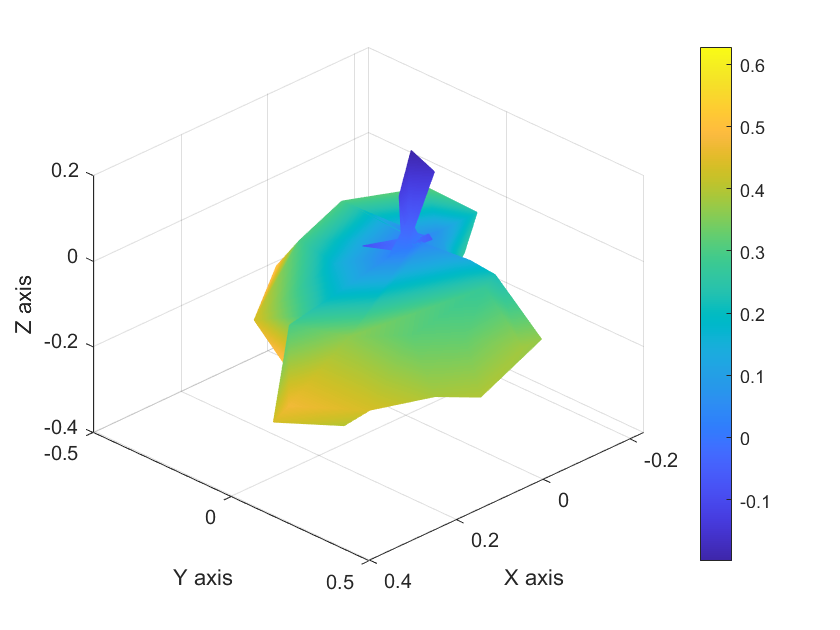

dataVals = SH.getData(ODFdata.getValues(8,10,1,0,0));
expt.visualizeODF(dataVals, gt.table);